% readmatrix conveniently reads in our data!
qPCR = readmatrix("qPCRdata.xls")

qPCR =          0    1.7688    1.8627    1.7444
    2.0000    0.9169   -0.0315    0.5173
    4.0000   -2.2275   -0.7407   -0.7346
    6.0000   -1.0689   -1.6025   -1.6517
    8.0000   -0.9387   -1.1601   -0.9511
   10.0000   -0.6538    0.7448   -0.3936
   12.0000    1.2832    2.2045    1.9442
   14.0000    3.1713    3.7086    2.4265
   16.0000    5.8873    4.4338    3.5636
   18.0000    5.8847    3.8963    4.0953


% Now we need to split the independent and dependent variables
% Create one matrix 'PCRvals' that holds the qPCR output (last 3 columns)
% and one vector 'ObsTime' that holds the timepoints
PCRvals=qPCR(:,2:end); % index the matrix to get all rows, all columns from 2nd to end
ObsTime = qPCR(:,1); % index to get all rows, the whole first column

% The qPCR data is in log2 ratios- convert them to raw ratios
% (hint: 2^each value)
PCRvals = 2.^PCRvals

PCRvals =     3.4078    3.6369    3.3507
    1.8881    0.9784    1.4313
    0.2135    0.5984    0.6010
    0.4767    0.3293    0.3183
    0.5217    0.4475    0.5172
    0.6356    1.6758    0.7612
    2.4338    4.6092    3.8482
    9.0087   13.0737    5.3757
   59.1897   21.6130   11.8240
   59.0849   14.8898   17.0920


% Calculate the average value at each time point across the replicates
% and calculate the standard error of their means (SEM)
% (hint: look up mean, stdev; calculate sem from stdev!)
meanPCR=mean(PCRvals,2); % mean of three replicates
stdevPCR=std(PCRvals,0,2); % standard deviation of three replicates
semPCR=stdevPCR./sqrt(3); % standard error of the mean

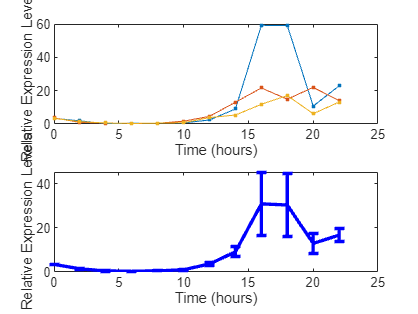

% Plot the raw data and the mean curve with error bars!
% (hint: use 'subplot' and 'errorbar')
subplot(2,1,1);
plot(ObsTime,PCRvals,'.-')
xlabel('Time (hours)');
ylabel('Relative Expression Levels');
subplot(2,1,2)
errorbar(ObsTime,meanPCR,semPCR,'b', 'LineWidth',2);
xlabel('Time (hours)')
ylabel('Relative Expression Levels')